fseries = fourier_series(4, 20);

The fourier series is : 


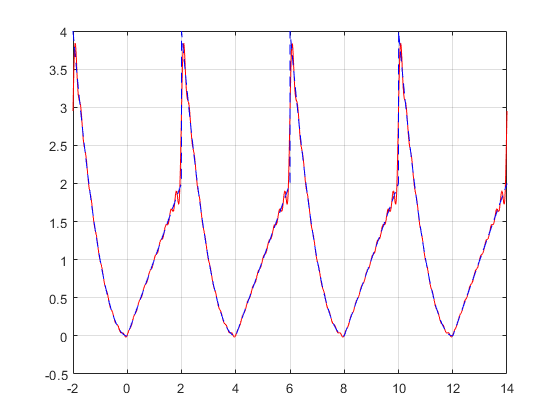

x = linspace(-2, 14, 1000);
y = subs(fseries, x);
plot(x, y, 'r');
hold on;
f = @(x) (x.^2).*(-2 <= x & x < 0) + (x).*(0 <= x & x <= 2);
x = linspace(-2, 2, 1000);
y = f(x);
ry = repmat(y, 1, 4);
rx = linspace(-2, 14, length(ry));
plot(rx, ry, 'b--');
grid on;
hold off;

fseries = fourier_series(2*pi, 20);

The fourier series is : 


$$\frac{1911387046407553\,\sin\left(3\,x\right)}{4503599627370496}+\frac{5734161139222659\,\sin\left(5\,x\right)}{22517998136852480}+\frac{5734161139222659\,\sin\left(7\,x\right)}{31525197391593472}+\frac{1911387046407553\,\sin\left(9\,x\right)}{13510798882111488}+\frac{521287376292969\,\sin\left(11\,x\right)}{4503599627370496}+\frac{441089318401743\,\sin\left(13\,x\right)}{4503599627370496}+\frac{1911387046407553\,\sin\left(15\,x\right)}{22517998136852480}+\frac{5734161139222659\,\sin\left(17\,x\right)}{76561193665298432}+\frac{5734161139222659\,\sin\left(19\,x\right)}{85568392920039424}+\frac{5734161139222659\,\sin\left(x\right)}{4503599627370496}$$

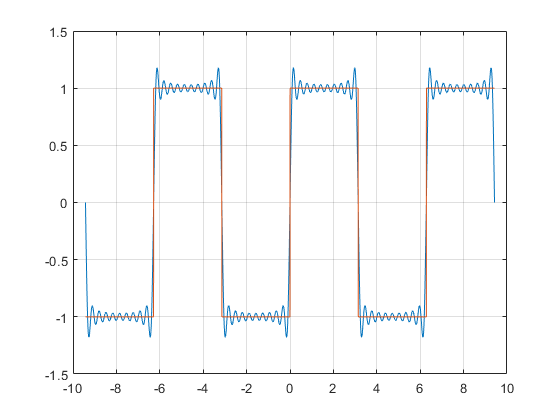

x = linspace(-3*pi, 3*pi, 1000);
y = subs(fseries, x);
plot(x, y);
hold on;

f = @(x) (-1).*(-pi <= x & x < 0 ) + (1).*(0 <= x & x <= pi);
x = linspace(-pi, pi, 1000);
y = f(x);

ry = repmat(y, 1, 3);
rx = linspace(-3*pi, 3*pi, length(ry));
plot(rx, ry);
grid on;
hold off;